# Integrated ORP-HTL Model (Single County)

This live script is used to run the integrated microalgae model. The modules within the integrated model include:

- **Thermal Model:** Determines pond temperatures and evaporation with hourly resolution in the location of interest

- **Growth Model: **Determines the microalgae growth rate with hourly resolution in the location of interest

- **Cultivation and Dewatering Model:** Determines energy consumption for pumps and paddlewheels, consumption of ammonia, DAP, and CO2, blue and green water footprint, and the net biomass output from cultivation in Open Raceway Ponds (ORPs) with a 3-stage dewatering process (bioflocculation, membrane separation, and centrifugation)

- **Storage Model:** Determines additional requirements for long-term (6+ months) anaerobic biomass storage to offset seasonal production variability, storage losses, and the resulting biomass composition sent to fuel conversion

- **HTL and Fuel Upgrading Model: **Determines energy and consumables for Hydrothermal Liquefaction (HTL) to convert algae biomass into biocrude, energy and consumables for fuel upgrading via hydrotreating and hydrocracking to produce renewable diesel and naphtha from biocrude, and the resulting annual fuel output based on biomass composition and reactor configuration

- **Techno-Economic Analysis (TEA): **Determines the total capital expenditure and annual operational expenses for the integrated biorefinery and solves for the minimum fuel and minimum biomass selling prices using a 30-year discounted cash flow rate of return (DCFROR) analysis with standard Nth-plant economic assumptions

- **Life Cycle Assessment (LCA):** Determines the life cycle environmental impacts of the integrated biorefinery across all 10 impact categories from the Tool for the Reduction and Assessment of Chemical and other environmental Impacts (TRACI 2.1), and total freshwater consumption 

## Step 1: Define Inputs for the Process Model

While some of the model inputs are adjustable by the user, many inputs are built into the model to increase ease-of-use and ensure accurate reporting. The adjustable inputs are defined by the use below:

### 1.1 Facility Location:

clear
clc
load background_data.mat county_dat
states_val = unique(county_dat(:,4));
State = states_val(4);
states_indx = find(strcmp(county_dat(:,4),State));
county_val = unique(county_dat(states_indx,3)); 

try
County = county_val(36);
catch
County = county_val(1);
end

% Weather file path
[file_ids,weather_script,coords] = weather_finder(County,State);

% Parse weather
T_amb= (weather_script(:,4)); % ambient temperature deg C
RH= weather_script(:,5); % relative humidity (%)
WNDSPD= weather_script(:,3); % wind speed (m per sec)
GHI= weather_script(:,2); % GHI (W per m2) 

Rainfall = "Off";
    if Rainfall == "On"
    rainfall_mat = weather_script(:,6)/1000; % m per hr, hourly average
    else 
    rainfall_mat = zeros(8760,1);
    end 

Value = [County; max(weather_script(:,1)); mean(T_amb); mean(RH); (sum(GHI)/max(weather_script(:,1)))/1000; (sum(rainfall_mat)/max(weather_script(:,1)))*100/2.54];
fprintf('Average Weather Parameters for %s County (Average of %.0f Weather Stations)  \nAverage Ambient Temperature = %.1f degrees C \nAverage Relative Humidity = %.0f%% \nTotal Global Horizonatl Irradiance (GHI) = %.1f kWh/m2 \nTotal Annual Rainfall = %.1f inches \n', Value);

Average Weather Parameters for San Diego County (Average of 6 Weather Stations)  
Average Ambient Temperature = 19.2 degrees C 
Average Relative Humidity = 50% 
Total Global Horizonatl Irradiance (GHI) = 2152.3 kWh/m2 
Total Annual Rainfall = 0.0 inches 


### 1.2 Facility Size and Layout:

Select the facility size in total wetted acres and specify the size of individual ponds. Expect the MBSP and MFSP to increase significantly with facility sizes smaller than 5000 wetted-acres due to economies of scale.

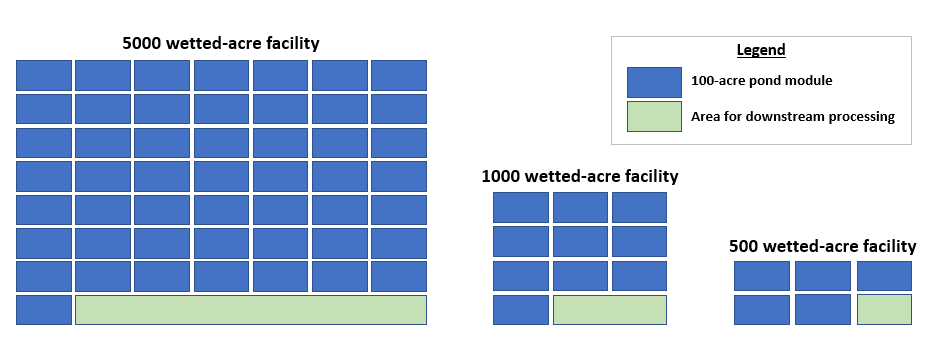

wetted_acres = 5000; % wetted-acres
pond_size = 10; % acres
depth = 0.2; % m
max_depth = 0.25*100; % enter in m, converted to cm
min_depth = 0.15*100; % enter in m, converted to cm

*"Max Pond Depth" must be greater than "Pond Depth" and "Min Pond Depth" must be less than "Pond Depth" specified above. When heavy rainfall ocurrs, the model may "break" if the the pond must be drained below the minimum specified depth. If rainfall is "On," the minimum pond depth should be set very low (0.01 - 0.05 m) to avoid issues with pond volume and harvesting.  *

% Facility Size and Layout 
num_ponds = ceil(wetted_acres/pond_size);
module_size = 100; % wetted-acres (fixed)
    if pond_size == 10
        if wetted_acres == 5000
            length_orp = 2*670*7; % m --> module is 2 ponds wide (670 m length per pond); Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        else 
            length_orp = 2*670*3; % m --> total length for 5000 wetted acres with 10-acre ponds is 10070.4 m in Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        end 
    else 
        if wetted_acres == 5000
            length_orp = 4*417*7; % m --> module is 2 ponds wide (670 m length per pond); Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        else 
            length_orp = 4*417*3; % m --> total length for 5000 wetted acres with 10-acre ponds is 10070.4 m in Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        end 
    end 

% Model Input Vectors 
geom_vec = [length_orp width depth max_depth min_depth] ;

### 1.3 Harvesting Sequence:

Define harvesting parameters for the cultivation facility including the pond inoculation concentration, the concentration at which harvesting is triggered, and maximum days between automated harvesting events (regardless of pond concentration). If "Rainfall" is turned on, harvesting is also triggered when rainfall causes the pond depth to exceed the maximum allowable depth specified above. *Please note the harvesting concentration must be greater than the inoculation concentration.*

% Harvest sequence, concentrations in gpL and days to harvest
CX_inoculation = 0.1*1000; % entered as gpL and converted to g/m3
CX_harvesting = 0.6*1000; % entered as gpL and converted to g/m3
harv_days = 5; % days until automated harvest cycle is triggered

%Build model input vectors
harvest_vec = [CX_inoculation CX_harvesting harv_days 250 4000]; %[initial_CX final_CX days_to_harvest i_salt salt_max_cx]

strain = "S_obliquus"; 
strain_vec =[305.4, 276.2, 314.1, 0.38, 480, 0.03, 1.5]; %[max temp, min temp, optimal temp, ODC, sat light intensity, dark respiration losses, phi] - phi is photon efficiency of 12 g biomass/8 mol photons = 1.5

### 1.4 Nutrients and CO2 Consumption Parameters:

Define the C, N, and P content of the microalgae to quantify the consumption of ammonia, DAP, and CO2 used for cultivation. *Please enter percentages as fractions (for example, 25% is entered as 0.25).*

**    Carbon Content and Carbon Utilization and Capture Efficiencies:**

c_content = 0.54; % ash-free dry weight basis 
sparge_eff =  0.9;

%Optional inputs to include CO2 capture energy and emissions in boundary
CO2_capture_elec_en = 0; %MJ elec/tCO2 captured supplied by local grid
CO2_capture_therm_en = 0;  %MJ thermal/tCO2 captured supplied by NG - enter 0 and include emissions from thermal energy gen. in indirect emissions when using waste heat 
CO2_capture_indir_GHG = 0;  %GHG from CO2 capture consumables (MEA, water, other chemicals, sorbents, solvents, etc.) - will vary based on CO2 capture tech.

%Build model input vectors
co2_capt_lci = [CO2_capture_indir_GHG; CO2_capture_therm_en; CO2_capture_elec_en];

**    N + P Content in Algae and Nutrients:**

rep_dep = "Nutrient Replete";
p_content = 0.0022; % ash-free dry weight basis
n_content = 0.018; % ash-free dry weight basis
p_content_dap = 0.2; % dw basis
n_content_dap = 0.18; % dw basis
n_content_ammonia = 0.82; % dw basis

    switch rep_dep
        case 'Nutrient Replete'
        nutrient_surpluss = 0.2; % percentage surplus of nutrients supplied
        case 'Nutrient Deplete'
        nutrient_surpluss = 0.0; % percentage surplus of nutrients supplied 
    end 

**Transportation distances for Ammonia:**

% Ecoinvent default: 276 km by freight train, 47 km by freight-inland waterways, 148 km  by freigh lorry-unspecified, 
% 841 km by sea container ship - transportation distances in km
ammonia_transp_lorry = 148;
ammonia_transp_train = 276;
ammonia_transp_inland_ww = 47;
ammonia_transp_sea_container = 841;

**Transportation Distances for DAP:**

% Ecoinvent default: 276 km by freight train, 47 km by freight-inland waterways, 148 km  by freigh lorry-unspecified, 
% 841 km by sea container ship - transportation distances in km
DAP_transp_lorry = 148;
DAP_transp_train = 276;
DAP_transp_inland_ww = 47;
DAP_transp_sea_container = 841;

transp_vec = [ammonia_transp_train, ammonia_transp_inland_ww, ammonia_transp_lorry, ammonia_transp_sea_container; % ammonia
              DAP_transp_train, DAP_transp_inland_ww, DAP_transp_lorry, DAP_transp_sea_container]; % DAP

### 1.5 Inputs for Composition and Anaerobic Storage:

**Microalgae Composition (dry weight basis):**

*Please note the algae composition must sum to 100% (proteins + carbohydrates + lipids + ash = 100%).*

prot = 0.09; % dry wt%
carb = 0.421; % dry wt%
lip = 0.412; % dry wt%
ash = 0.077; % dry wt%

sum_comp = (prot + carb + lip + ash)*100;
fprintf('Current Sum = %0.2f %%', sum_comp);

Current Sum = 100.00 %

**Anaerobic Storage Parameters:**

degradation = 0.25; % dry matter lost to acid formation - based on Wendt et al., 2019 (INL)
centr_out_dens = 1042; %kg/m3 - Li et al., 2020
pump_eff = 0.7; % pumping efficiency

% Build comp_vector now that all parameters are defined
comp_vector = [c_content sparge_eff p_content p_content_dap n_content_dap n_content n_content_ammonia nutrient_surpluss ash];

### 1.6 Inputs for Hydrothermal Liquefaction (HTL) and Fuel Upgrading

The composition of the microalgae can significantly impact HTL performance. The composition (as harvested) is defined above under "Microalgae Composition (dry weight basis)" and to evaluate HTL performance for locations where seasonal variability is minimal or will not be considered, storage losses can be set to 0% to represent this scenario.

annual_uptime = 330; % days per year in full operation
res_time = 15; % minutes

% Additional Inputs Required to Run HTL Module
fac_size = wetted_acres; 
reactor_diam = 0.667; %ft (8 inches) - Chen et al., 2021

Char_recovery = 1; % percent of HTL solids (char) recovered and sold as biochar co-product 
NH3EQ_recovery = 1; % of NH3 exiting HTL recovered from the aqueous phase
DAPEQ_recovery = 1; % of DAP exiting HTL recovered from the aqueous phase

### 1.7 Inputs for the Techno-Economic Analysis

Use this section to define commodity prices such as ammonia, DAP, electricity, and CO2 and to define critical assumptions for the cash flow analysis.

**Assumptions for the Discounted Cash Flow Rate of Return Model:**

Cost_year = 2019; % cost year used to adjust CAPEX and OPEX
IRR = 0.1; % Internal Rate of Return in DCFROR 

**Commodity Prices and Transportation Distances:**

*Default commodity prices are reported in 2019 dollars. Enter commodity prices in 2019 dollars and all costs are indexed within the model to the "Cost Year" entered above.*

Cultivation Consumables:

%Commodity prices
Elec_cost = 0.07; % 2019$/kWh - EIA (2019)
CO2_cost = 235; % $/tCO2
ammonia_cost = 0.8; % $/kg in 2019 USD (from $0.39/lb in 2011 dollars - Davis et al.)
dap_cost = 0.66; % $/kg in 2019 USD (from $0.32/lb in 2011 dollars - Davis et al.)

HTL and Upgrading Consumables:

NG_cost = 0.2154; % 2011$/kg - $5.10/1000 scf - Dutta et al., 2011; indexed to 2019 dollars
H_cost = 1.47; % 2012$/kg - Dilich et al., 2012; indexed to 2019 dollars
Process_water_cost = 0.204/1000; % $/m3 converted to $/kg - 2011$/kg - Dutta et al., 2011; indexed to 2019 dollars
NH3EQ_value = 0.8; % $/kg in 2019 USD (from $0.39/lb in 2011 dollars - Davis et al.)
DAPEQ_value = 0.66; % $/kg in 2019 USD (from $0.32/lb in 2011 dollars - Davis et al.)
Char_value = 0.1; % 2019$/kg - Assumption

% Critical Inputs Cost Matrix
cost_matrix = [Elec_cost, ammonia_cost, dap_cost, CO2_cost]; %$/kWh, $/kg ammonia, $/kg DAP, $/tCO2

## Step 2: Run the Model with the Current Inputs

 
% Run the thermal, cultivation, and dewatering models to get critical
% outputs used in the HTL and upgrading functions

%paramters used in optimization that are not used here
prod_scale = 1.46;
nut_rem = 0; 
rec_P = 0;
grid_red = 0; 

% Pre-allocate output variables
Cult_Out_Station_D = zeros(26, size(coords,1));
HTL_process_mod_out_D = zeros(25, size(coords,1)); 
pond_temps_mat = zeros(4, size(coords,1)); 
cult_TEA_out_CAPEX_D = zeros(61,size(coords,1)); 
cult_TEA_out_OPEX_D = zeros(9,size(coords,1));
HTL_UG_CAPX_OPX_D = zeros(64, size(coords,1)); 
storage_fcn_out_D = zeros(12, size(coords,1)); 
MBSP = zeros(size(coords,1),1); 
MFSP = zeros(size(coords,1),1);
aware_cult_1_D = zeros(size(coords,1), 13);
aware_cult_2_D = zeros(size(coords,1), 13); 
cash_flow_mbsp_3D = zeros(33, 24, size(coords,1)); 
cash_flow_mfsp_3D = zeros(33, 24, size(coords,1)); 
bC_HTL_gas_D = zeros(1,size(coords,1));

for i = 1:size(coords,1) 
    weather_input = weather_script(weather_script(:,1) == i, [4,5,2,3]);
    T_amb = weather_script(weather_script(:,1) == i, 4);
    RH = weather_script(weather_script(:,1) == i, 5);
    GHI = weather_script(weather_script(:,1) == i, 2);
    WNDSPD = weather_script(weather_script(:,1) == i, 3);
    
    if Rainfall == "On"
    rainfall_mat = weather_script(weather_script(:,1) == i, 6)/1000; % m per hr, hourly average
    else 
    rainfall_mat = zeros(8760,1);
    end 
    
    % Thermal Model
    [TR,evap_rate, Water_con, M_Evap] = thermal_fcnV6(weather_input,geom_vec); 
   
    % Thermal Model Outputs
    annual_evap_cm_day = evap_rate(1,5);
    pond_temps_mat(:,i) = [max(TR)-273.15; min(TR)-273.15; mean(TR)-273.15; annual_evap_cm_day];
    
    % Cultivation and Storage Functions
    [CX, centr_out, centr_out_ann, cult_out, water_vol, CO2_demand_hourly,aquifer_hrly, area, total_recycled, num_settling_ponds, settlers_out, membrane_out,aware_cult, nutrients, recycled_membr_centr, dep_rep_scaling, harvest_water, Conc_at_Harvest, light_eff_track, aquifer, rec_algae, biomass_balance, energy_balance, dewatering_mat, check_biomass] = cultivation_fcn([TR GHI M_Evap rainfall_mat],geom_vec,strain_vec, harvest_vec, comp_vector, rep_dep, prod_scale, carb, lip, prot);
    [storage_fcn_out, ann_ave_centr, biomass_balance_st, comp_ann_ave_centr] = Storage_fcn(prot, carb, lip, ash, centr_out, centr_out_dens, degradation, pump_eff);
    
        % Protein extraction and value recovery
        if rec_P > 0
    
        protein_out_storage = biomass_balance_st(2,3); %kg protein per year
        protein_diverted = rec_P*protein_out_storage; %kg protein/yr diverted and recovered
        protein_value = 2; %dollars per kg protein product
        protein_revenue = protein_diverted*protein_value; % $5/kg per kg protein diverted and recovered as annual revenue
        
        ann_ave_centr = (ann_ave_centr*8760 - protein_diverted)/8760; %kg/hr - protein diverted (kg/hr)
        
        conv_feed_prot =  protein_out_storage*(1-rec_P); 
        conv_feed_carb = biomass_balance_st(3,3); 
        conv_feed_lip = biomass_balance_st(4,3); 
        conv_feed_ash = biomass_balance_st(5,3); 
        conv_feed_total = conv_feed_prot + conv_feed_carb + conv_feed_lip + conv_feed_ash; % kg DW/hr (includes ash)
        
        prot_n = conv_feed_prot/conv_feed_total; 
        carb_n = conv_feed_carb/conv_feed_total; 
        lip_n = conv_feed_lip/conv_feed_total; 
        ash_n = conv_feed_ash/conv_feed_total; 
    
        water_in = ann_ave_centr*8760*0.80; %total kg water in = water out
        AFDW_out = conv_feed_prot + conv_feed_carb + conv_feed_lip;
        ppe_TSS = AFDW_out/(AFDW_out + water_in); 
          
        %Mass balance for protein extraction
        biomass_balance_PE(1,1) = protein_diverted;
        biomass_balance_PE(2,1) = protein_diverted;
        biomass_balance_PE(3,1) = 0;
        biomass_balance_PE(4,1) = 0;
        biomass_balance_PE(5,1) = 0;
        
        biomass_balance_PE(1,2) = conv_feed_total;
        biomass_balance_PE(2,2) = conv_feed_prot;
        biomass_balance_PE(3,2) = conv_feed_carb;
        biomass_balance_PE(4,2) = conv_feed_lip;
        biomass_balance_PE(5,2) = conv_feed_ash;
    
        % Biomass mass balance between cultivation, dewatering, storage and protein extraction
        comp_biomass_balance = [biomass_balance biomass_balance_st biomass_balance_PE]; 
        
        % Outputs to conversion 
        algae_comp_to_con = [prot_n; carb_n; lip_n; ash_n; ppe_TSS]; 
        areal_prod_adj = sum(centr_out)*0.20*1000/area/365; %productivity calculated using centr_out (after dewatering) - 20% solids is on an AFDW basis
        areal_prod_adj_st = ann_ave_centr*8760*ppe_TSS*1000/area/365; %productivity calculated using storage_fcn ann_ave_centr flow (including losses) - 20% solids is on an AFDW basis
    
        else 
        %Protein revenue is zero
        protein_revenue = 0; 

        % Biomass mass balance between cultivation, dewatering, storage
        comp_biomass_balance = [biomass_balance biomass_balance_st];
            
        % Composition and solids from storage - ps: post-storage
        prot_n = str2double(storage_fcn_out(3,2));
        carb_n = str2double(storage_fcn_out(4,2));
        lip_n = str2double(storage_fcn_out(5,2));
        ash_n = str2double(storage_fcn_out(6,2));
        TSS_n = str2double(storage_fcn_out(12,2));
    
        % Outupts to conversion
        algae_comp_to_con = [prot_n; carb_n; lip_n; ash_n; TSS_n];
        areal_prod_adj = sum(centr_out)*0.20*1000/area/365; %productivity calculated using centr_out (after dewatering) - 20% solids is on an AFDW basis
        areal_prod_adj_st = ann_ave_centr*8760*TSS_n*1000/area/365; %productivity calculated using storage_fcn ann_ave_centr flow (including losses) - 20% solids is on an AFDW basis
    
        end

    % Areal Productivity Calcs at different stages
    areal_prod = str2double(cult_out(2,2)); %productivity calculated in cultivation function 

    % Cultivation TEA Function
    [cult_TEA_out_CAPEX, cult_TEA_out_OPEX] = Cultivation_TEA_fcn(Cost_year, num_ponds, pond_size, module_size, CO2_demand_hourly, aquifer_hrly, total_recycled, storage_fcn_out, num_settling_ponds, settlers_out, membrane_out, cult_out, cost_matrix, recycled_membr_centr, nut_rem);

    % HTL and Upgrading Model
    [HTL_process_mod_out, HTL_UG_CAPX_OPX, direct_cap, case_number, biogenic_c_in_gas_phase] = HTL_and_UG_fcn(prot_n, carb_n, lip_n, ash_n , areal_prod_adj_st, fac_size, res_time, reactor_diam, annual_uptime, Char_recovery, NH3EQ_recovery, DAPEQ_recovery, Cost_year, NG_cost, H_cost, Elec_cost, Process_water_cost, NH3EQ_value, DAPEQ_value, Char_value, cult_out, nut_rem);
    
    % DCFROR for Minimum Bioass Selling Price
    total_tonnes_AFDW = str2double(cult_out(1,2)); %tonnes AFDW/yr
    land_CAPEX = str2double(cult_TEA_out_CAPEX(59,2));
    equip_fac_CAPEX = str2double(cult_TEA_out_CAPEX(58,2));
    working_CAPEX = 0.05*equip_fac_CAPEX; 
    total_OPEX = str2double(cult_TEA_out_OPEX(9,2)); 

    options = optimset('Display','off');

    fun = @NPV_MBSP;
    x0 = 1;
    MBSP(i,1) = fsolve(fun, x0, options, total_tonnes_AFDW, land_CAPEX, equip_fac_CAPEX, working_CAPEX, total_OPEX, IRR);
    [NPV, cash_flow] = NPV_MBSP(MBSP(i,1), total_tonnes_AFDW, land_CAPEX, equip_fac_CAPEX, working_CAPEX, total_OPEX, IRR);

    % DCFROR for Minimum Fuel Selling Price
    GGE_per_yr = str2double(HTL_process_mod_out(12,2)); %GGE/yr
    land_CAPEX = str2double(cult_TEA_out_CAPEX(59,2)); %from cultivation (includes area for downstream processing)
    total_equip_fac_CAPEX = str2double(cult_TEA_out_CAPEX(58,2)) + str2double(HTL_UG_CAPX_OPX(45,2));
    total_working_CAPEX = 0.05*total_equip_fac_CAPEX;
    total_combined_OPEX = str2double(cult_TEA_out_OPEX(9,2)) + str2double(HTL_UG_CAPX_OPX(53,2)) + str2double(HTL_UG_CAPX_OPX(64,2));
    total_coprod_rev = str2double(HTL_UG_CAPX_OPX(58,2)) + protein_revenue;

    fun = @NPV_MFSP;
    x0 = 0.1;
    MFSP(i,1)= fsolve(fun, x0, options, GGE_per_yr, land_CAPEX, total_equip_fac_CAPEX, total_working_CAPEX, total_combined_OPEX, IRR, total_coprod_rev);
    [NPV_mfsp, cash_flow_mfsp] = NPV_MFSP(MFSP(i,1), GGE_per_yr, land_CAPEX, total_equip_fac_CAPEX, total_working_CAPEX, total_combined_OPEX, IRR, total_coprod_rev);
      
    % Combined Outputs (for each weather station)
    Cult_Out_Station_D(:,i) = cult_out(:,2); 
    HTL_process_mod_out_D(:,i) = HTL_process_mod_out(:,2);
    cult_TEA_out_CAPEX_D(:,i) = cult_TEA_out_CAPEX(:,2); 
    cult_TEA_out_OPEX_D(:,i) = cult_TEA_out_OPEX(:,2); 
    HTL_UG_CAPX_OPX_D(:,i) = HTL_UG_CAPX_OPX(:,2); 
    storage_fcn_out_D(:,i) = storage_fcn_out(:,2);
    cash_flow_mbsp_3D(:,:,i) = table2array(cash_flow); 
    cash_flow_mfsp_3D(:,:,i) = table2array(cash_flow_mfsp); 
    bC_HTL_gas_D(:,i) = biogenic_c_in_gas_phase; 

    % AWARE Cultivation Metrics
    aware_cult_1_D(i,:) = aware_cult(1,:);
    aware_cult_2_D(i,:) = aware_cult(2,:); 

end 
    
% LCA model uses outputs from cultivation model from all weather stations to find averaege LCA metrics for each County
[process_lca, stage_breakdwn,stage_breakdwn_prc, consum_breakdwn, consum_breakdwn_prc,wsf_monthly, traci_vec, cf_vec, nerc_out, bC_balance] = LCA_HTL_ext(co2_capt_lci,Cult_Out_Station_D,storage_fcn_out_D,HTL_process_mod_out_D,coords(i,:),direct_cap,file_ids{i}, aware_cult_1_D, aware_cult_2_D,transp_vec, annual_uptime, grid_red, bC_HTL_gas_D);
wsf_cult_D = wsf_monthly(13,1); % m3-eq/tonne AFDW
wsf_fuels_D = wsf_monthly(13,2); % m3-eq/MJ fuel

## Step 3: View Model Outputs

### Thermal Model Outputs:

pond_temps_mat_ave = [mean(pond_temps_mat(1,:)); mean(pond_temps_mat(2,:)); mean(pond_temps_mat(3,:)); mean(pond_temps_mat(4,:))];
fprintf('Pond Temperatures and Evaporation  \nMaximum Pond Temperature: %.1f degrees C \nMinimum Pond Temperature: %.1f degrees C \nAverage Pond Temperature: %.1f degrees C \nEvaporation Rate: %.2f cm/day', pond_temps_mat_ave);

Pond Temperatures and Evaporation  
Maximum Pond Temperature: 41.1 degrees C 
Minimum Pond Temperature: 7.8 degrees C 
Average Pond Temperature: 23.0 degrees C 
Evaporation Rate: 0.39 cm/day

### Cultivation Model Outputs: 

annual_ave_areal_prod = mean(Cult_Out_Station_D(2,:)); % g AFDW m-2 day-1
spring_ave_areal_prod =  mean(Cult_Out_Station_D(4,:)); % g AFDW m-2 day-1
summer_ave_areal_prod =  mean(Cult_Out_Station_D(5,:)); % g AFDW m-2 day-1
fall_ave_areal_prod =  mean(Cult_Out_Station_D(6,:)); % g AFDW m-2 day-1
winter_ave_areal_prod =  mean(Cult_Out_Station_D(7,:)); % g AFDW m-2 day-1
total_tonnes_AFDW =  mean(Cult_Out_Station_D(1,:)); %tonnes AFDW/yr

prod_mat = [annual_ave_areal_prod; spring_ave_areal_prod; summer_ave_areal_prod; fall_ave_areal_prod; winter_ave_areal_prod; total_tonnes_AFDW];
fprintf('Biomass Productivity  \nAnnual Average Areal Productivity: %.2f g AFDW m-2 day-1\nSpring Areal Productivity: %.2f g AFDW m-2 day-1\nSummer Areal Productivity: %.2f g AFDW m-2 day-1\nFall Areal Productivity: %.2f g AFDW m-2 day-1\nWinter Areal Productivity: %.2f g AFDW m-2 day-1\nTotal Biomass Production: %.0f tonnes AFDW/yr', prod_mat);

Biomass Productivity  
Annual Average Areal Productivity: 27.65 g AFDW m-2 day-1
Spring Areal Productivity: 31.40 g AFDW m-2 day-1
Summer Areal Productivity: 35.30 g AFDW m-2 day-1
Fall Areal Productivity: 26.62 g AFDW m-2 day-1
Winter Areal Productivity: 17.02 g AFDW m-2 day-1
Total Biomass Production: 204205 tonnes AFDW/yr

water_pump_en = mean(Cult_Out_Station_D(11,:)); % kWh/yr
paddlewheel_en = mean(Cult_Out_Station_D(12,:)); % kWh/yr
sparge_en = mean(Cult_Out_Station_D(13,:)); % kWh/yr
membrane_en = mean(Cult_Out_Station_D(14,:)); % kWh/yr
cent_en = mean(Cult_Out_Station_D(15,:)); % kWh/yr
makeup_water = mean(Cult_Out_Station_D(17,:)); % kWh/yr

ammonia_con = mean(Cult_Out_Station_D(8,:)); % kg/yr
dap_con = mean(Cult_Out_Station_D(9,:)); % kg/yr
CO2_con = mean(Cult_Out_Station_D(10,:)); % kg/yr

proc_consum_mat = [water_pump_en; paddlewheel_en; sparge_en; membrane_en; cent_en; ammonia_con; dap_con; CO2_con];
fprintf('Cultivation Energy\nWater Pumping Energy: %.0f kWh/yr\nPaddlewheel Energy: %.0f kWh/yr\nCO2 Sparging Energy: %.0f kWh/yr\nMembrane Energy (Dewatering): %.0f kWh/yr\nCentrifugation Energy (Dewatering): %.0f kWh/yr\n\nProcess Consumables\nAmmonia Consumption: %.0f kg/yr\nDAP Consumption: %.0f kg/yr\nCO2 Consumption: %.0f tonnes CO2/yr\n ', proc_consum_mat);

Cultivation Energy
Water Pumping Energy: 22907833 kWh/yr
Paddlewheel Energy: 40658691 kWh/yr
CO2 Sparging Energy: 17565752 kWh/yr
Membrane Energy (Dewatering): 948365 kWh/yr
Centrifugation Energy (Dewatering): 2449790 kWh/yr

Process Consumables
Ammonia Consumption: 5058527 kg/yr
DAP Consumption: 2842563 kg/yr
CO2 Consumption: 449252 tonnes CO2/yr
 

### HTL and Upgrading Model Outputs: 

% HTL phase yields
biocrude_yield = mean(HTL_process_mod_out_D(18,:))*100; % wt% AFDW algae
aqueous_yield = mean(HTL_process_mod_out_D(19,:))*100; % wt% AFDW algae
solids_yield = mean(HTL_process_mod_out_D(20,:))*100; % wt% AFDW algae
gas_yield = mean(HTL_process_mod_out_D(21,:))*100; % wt% AFDW algae

% Total fuel production
total_biocrude = mean(HTL_process_mod_out_D(9,:))/1000000; % MM Gallons/yr
total_diesel = mean(HTL_process_mod_out_D(7,:))/1000000; % MM Gallons/yr
total_naphtha = mean(HTL_process_mod_out_D(8,:))/1000000; % MM Gallons/yr
total_GGE = mean(HTL_process_mod_out_D(12,:))/1000000; % MM GGE/yr
total_MJ = mean(HTL_process_mod_out_D(13,:)); % MJ fuel/yr

% Co-products production
total_NH3EQ = mean(HTL_process_mod_out_D(16,:)); % kg/yr
total_DAPEQ = mean(HTL_process_mod_out_D(17,:)); % kg/yr
total_Char_EQ = mean(HTL_process_mod_out_D(15,:)); % kg/yr

% Process Consumables
total_grid_elec = mean(HTL_process_mod_out_D(5,:)); % kWh/yr
total_NG = mean(HTL_process_mod_out_D(3,:)); % kg/yr
total_hydrogen = mean(HTL_process_mod_out_D(2,:)); % kg/yr
total_proc_water = mean(HTL_process_mod_out_D(4,:)); % kg/yr

HTL_out_mat = [biocrude_yield; aqueous_yield; solids_yield; gas_yield; total_biocrude; total_diesel; total_naphtha; total_GGE; total_MJ; total_NH3EQ; total_DAPEQ; total_Char_EQ; total_grid_elec; total_NG; total_hydrogen; total_proc_water];
fprintf('HTL Phase Yields\nBiocrude Yield: %.0f wt%% AFDW algae\nAqueous Yield: %.0f wt%% AFDW algae\nSolids (Char) Yield: %.0f wt%% AFDW algae\nGas Yield: %.0f wt%% AFDW algae\n\nTotal Fuel Production\nTotal Biocrude Production: %.0f MM Gallons/yr\nTotal Renewable Diesel: %.0f MM Gallons/yr\nTotal Naphtha: %.0f MM Gallons/yr\nTotal GGE: %.2f MM GGE/yr\nTotal MJ Fuel: %.2e MJ Fuel/yr\n\nTotal Co-Products Production\nRecovered NH3: %.0f kg/yr\nRecovered DAP: %.0f kg/yr\nRecovered Biochar: %.0f kg/yr\n\nProcess Consumables\nTotal Grid Electricity: %.0f kWh/yr\nTotal Natural Gas: %.0f kg/yr\nTotal Hydrogen: %.0f kg/yr\nTotal Process Water: %.0f kg/yr\n', HTL_out_mat);

HTL Phase Yields
Biocrude Yield: 48 wt% AFDW algae
Aqueous Yield: 11 wt% AFDW algae
Solids (Char) Yield: 15 wt% AFDW algae
Gas Yield: 18 wt% AFDW algae

Total Fuel Production
Total Biocrude Production: 69 MM Gallons/yr
Total Renewable Diesel: 19 MM Gallons/yr
Total Naphtha: 4 MM Gallons/yr
Total GGE: 25.83 MM GGE/yr
Total MJ Fuel: 3.16e+09 MJ Fuel/yr

Total Co-Products Production
Recovered NH3: 5058527 kg/yr
Recovered DAP: 2842563 kg/yr
Recovered Biochar: 45477860 kg/yr

Process Consumables
Total Grid Electricity: 20255894 kWh/yr
Total Natural Gas: 1285777 kg/yr
Total Hydrogen: 4187770 kg/yr
Total Process Water: 102122715 kg/yr


### Techno-Economic Analysis Outputs:

    **Cultivation and Dewatering:**

% Cultivation and Dewatering CAPEX
total_ORP_capex = mean(cult_TEA_out_CAPEX_D(9,:))/1000000; % MM USD
total_incolum_capex = mean(cult_TEA_out_CAPEX_D(16,:))/1000000; % MM USD
total_CO2del_capex = mean(cult_TEA_out_CAPEX_D(23,:))/1000000; % MM USD
total_waterdel_capex = mean(cult_TEA_out_CAPEX_D(34,:))/1000000; % MM USD
total_dewat_capex = mean(cult_TEA_out_CAPEX_D(42,:))/1000000; % MM USD
total_storage_capex = mean(cult_TEA_out_CAPEX_D(47,:))/1000000; % MM USD
total_add_dir_capex = mean(cult_TEA_out_CAPEX_D(51,:))/1000000; % MM USD
total_add_indir_capex = mean(cult_TEA_out_CAPEX_D(57,:))/1000000; % MM USD
fixed_cap_inv = mean(cult_TEA_out_CAPEX_D(58,:))/1000000; % MM USD
land_capex = mean(cult_TEA_out_CAPEX_D(59,:))/1000000; % MM USD

cult_dew_capex = [total_ORP_capex; total_incolum_capex; total_CO2del_capex; total_waterdel_capex; total_dewat_capex; total_storage_capex; total_add_dir_capex; total_add_indir_capex; fixed_cap_inv; land_capex];
fprintf('Cultivation and Dewatering CAPEX\nORP CAPEX: %.0f MM USD\nInoculation System CAPEX: %.0f MM USD\nCO2 Delivery CAPEX: %.0f MM USD\nWater Delivery and Circulation CAPEX: %.0f MM USD\nDewatering CAPEX: %.0f MM USD\nStorage CAPEX: %.0f MM USD\nAdditional Direct CAPEX: %.0f MM USD\nIndirect CAPEX: %.0f MM USD\nFixed Capital Investment (Cultivation & Dewatering): %.0f MM USD\nLand CAPEX: %.0f MM USD', cult_dew_capex);

Cultivation and Dewatering CAPEX
ORP CAPEX: 187 MM USD
Inoculation System CAPEX: 17 MM USD
CO2 Delivery CAPEX: 11 MM USD
Water Delivery and Circulation CAPEX: 9 MM USD
Dewatering CAPEX: 56 MM USD
Storage CAPEX: 6 MM USD
Additional Direct CAPEX: 24 MM USD
Indirect CAPEX: 101 MM USD
Fixed Capital Investment (Cultivation & Dewatering): 410 MM USD
Land CAPEX: 24 MM USD

% Cultivation and Dewatering OPEX
total_energy_opex = mean(cult_TEA_out_OPEX_D(1,:))/1000000; % MM USD/yr
total_ammonia_opex = mean(cult_TEA_out_OPEX_D(2,:))/1000000; % MM USD/yr
total_DAP_opex = mean(cult_TEA_out_OPEX_D(3,:))/1000000; % MM USD/yr
total_CO2_opex = mean(cult_TEA_out_OPEX_D(4,:))/1000000; % MM USD/yr
total_labor_opex = mean(cult_TEA_out_OPEX_D(5,:))/1000000; % MM USD/yr
total_laborburdens_opex = mean(cult_TEA_out_OPEX_D(6,:))/1000000; % MM USD/yr
total_maint_opex = mean(cult_TEA_out_OPEX_D(7,:))/1000000; % MM USD/yr
total_taxins_opex = mean(cult_TEA_out_OPEX_D(8,:))/1000000; % MM USD/yr
total_cult_dewat_opex = mean(cult_TEA_out_OPEX_D(9,:))/1000000; % MM USD/yr

cult_dew_opex = [total_energy_opex; total_ammonia_opex; total_DAP_opex; total_CO2_opex; total_labor_opex; total_laborburdens_opex; total_maint_opex; total_taxins_opex; total_cult_dewat_opex];
fprintf('Cultivation and Dewatering OPEX\nElectricity OPEX: %.0f MM USD/yr\nAmmonia OPEX: %.0f MM USD/yr\nDAP OPEX: %.0f MM USD/yr\nCO2 OPEX: %.0f MM USD/yr\nLabor OEPX: %.0f MM USD/yr\nLabor Burdens: %.0f MM USD/yr\nMaintenance OPEX: %.0f MM USD/yr\nInsurance & Property Tax OPEX: %.0f MM USD/yr\nCultivation & Dewatering OPEX: %.0f MM USD/yr', cult_dew_opex);

Cultivation and Dewatering OPEX
Electricity OPEX: 7 MM USD/yr
Ammonia OPEX: 4 MM USD/yr
DAP OPEX: 2 MM USD/yr
CO2 OPEX: 106 MM USD/yr
Labor OEPX: 4 MM USD/yr
Labor Burdens: 4 MM USD/yr
Maintenance OPEX: 3 MM USD/yr
Insurance & Property Tax OPEX: 3 MM USD/yr
Cultivation & Dewatering OPEX: 132 MM USD/yr

fprintf('Estimated Minimum Biomass Selling Price %.2f USD/tonne AFDW', mean(MBSP));

Estimated Minimum Biomass Selling Price 929.94 USD/tonne AFDW

**    HTL and Fuel Upgrading:**

% HTL and Upgrading CAPEX
HTL_reactor_capex = mean(HTL_UG_CAPX_OPX_D(8,:))/1000000; % MM USD
upgrading_capex = mean(HTL_UG_CAPX_OPX_D(14,:))/1000000; % MM USD
heating_utility_capex = mean(HTL_UG_CAPX_OPX_D(20,:))/1000000; % MM USD
other_utility_capex = mean(HTL_UG_CAPX_OPX_D(33,:))/1000000; % MM USD
HTL_add_dir_capex = (mean(HTL_UG_CAPX_OPX_D(38,:))-mean(HTL_UG_CAPX_OPX_D(34,:)))/1000000; % MM USD
HTL_indir_capex = mean(HTL_UG_CAPX_OPX_D(44,:))/1000000; % MM USD
HTL_fixed_cap_inv = mean(HTL_UG_CAPX_OPX_D(45,:))/1000000; % MM USD

HTL_capex = [HTL_reactor_capex; upgrading_capex; heating_utility_capex; other_utility_capex; HTL_add_dir_capex; HTL_indir_capex; HTL_fixed_cap_inv];
fprintf('HTL and Fuel Upgrading CAPEX\nHTL Reactor CAPEX: %.0f MM USD\nUpgrading Equipment CAPEX: %.0f MM USD\nHeating Utility CAPEX: %.2f MM USD\nOther Utilities CAPEX: %.2f MM USD\nAdditional Direct CAPEX: %.0f MM USD\nIndirect CAPEX: %.0f MM USD\nFixed Capital Investment (HTL & Fuel Upgrading) %.0f MM USD', HTL_capex);

HTL and Fuel Upgrading CAPEX
HTL Reactor CAPEX: 48 MM USD
Upgrading Equipment CAPEX: 48 MM USD
Heating Utility CAPEX: 5.96 MM USD
Other Utilities CAPEX: 4.58 MM USD
Additional Direct CAPEX: 19 MM USD
Indirect CAPEX: 75 MM USD
Fixed Capital Investment (HTL & Fuel Upgrading) 200 MM USD

% HTL and Upgrading OPEX
grid_elec_opex = mean(HTL_UG_CAPX_OPX_D(51,:))/1000000; % MM USD/yr
NG_opex = mean(HTL_UG_CAPX_OPX_D(50,:))/1000000; % MM USD/yr
H2_opex = mean(HTL_UG_CAPX_OPX_D(49,:))/1000000; % MM USD/yr
water_opex = mean(HTL_UG_CAPX_OPX_D(52,:))/1000000; % MM USD/yr
labor_opex = mean(HTL_UG_CAPX_OPX_D(60,:))/1000000; % MM USD/yr
labor_burd_opex = mean(HTL_UG_CAPX_OPX_D(61,:))/1000000; % MM USD/yr
maint_opex = mean(HTL_UG_CAPX_OPX_D(62,:))/1000000; % MM USD/yr
ins_tax_opex = mean(HTL_UG_CAPX_OPX_D(63,:))/1000000; % MM USD/yr
total_HTL_UG_opex = (mean(HTL_UG_CAPX_OPX_D(53,:))+ mean(HTL_UG_CAPX_OPX_D(64,:)))/1000000; % MM USD/yr

HTL_opex = [grid_elec_opex; NG_opex; H2_opex; water_opex; labor_opex; labor_burd_opex; maint_opex; ins_tax_opex; total_HTL_UG_opex];
fprintf('HTL and Fuel Upgrading OPEX\nElectricity OPEX: %.2f MM USD/yr\nNatural Gas OPEX: %.2f MM USD/yr\nHydrogen OPEX: %.2f MM USD/yr\nProcess Water OPEX: %.2f MM USD/yr\nLabor OEPX: %.2f MM USD/yr\nLabor Burdens: %.2f MM USD/yr\nMaintenance OPEX: %.2f MM USD/yr\nInsurance & Property Tax OPEX: %.2f MM USD/yr\nHTL and Fuel Upgrading OPEX: %.0f MM USD/yr', HTL_opex);

HTL and Fuel Upgrading OPEX
Electricity OPEX: 1.42 MM USD/yr
Natural Gas OPEX: 0.26 MM USD/yr
Hydrogen OPEX: 5.77 MM USD/yr
Process Water OPEX: 0.02 MM USD/yr
Labor OEPX: 1.59 MM USD/yr
Labor Burdens: 1.43 MM USD/yr
Maintenance OPEX: 3.20 MM USD/yr
Insurance & Property Tax OPEX: 2.00 MM USD/yr
HTL and Fuel Upgrading OPEX: 16 MM USD/yr

% Co-Product Revenue
NH3EQ_rev = mean(HTL_UG_CAPX_OPX_D(56,:))/1000000; % MM USD/yr
DAPEQ_rev = mean(HTL_UG_CAPX_OPX_D(57,:))/1000000; % MM USD/yr
char_rev = mean(HTL_UG_CAPX_OPX_D(55,:))/1000000; % MM USD/yr
total_coprod_rev = mean(HTL_UG_CAPX_OPX_D(58,:))/1000000; % MM USD/yr

coprod_rev = [NH3EQ_rev; DAPEQ_rev; char_rev; total_coprod_rev];
fprintf('HTL and Fuel Upgrading Co-Product Revenue\nRecovered NH3: %.2f MM USD/yr\nRecovered DAP: %.2f MM USD/yr\nRecovered Biochar: %.2f MM USD/yr\nTotal Co-Products Revenue: %.0f MM USD/yr', coprod_rev);

HTL and Fuel Upgrading Co-Product Revenue
Recovered NH3: 4.05 MM USD/yr
Recovered DAP: 1.88 MM USD/yr
Recovered Biochar: 4.55 MM USD/yr
Total Co-Products Revenue: 10 MM USD/yr

fprintf('Estimated Minimum Fuel Selling Price %.2f USD/GGE', mean(MFSP));

Estimated Minimum Fuel Selling Price 8.57 USD/GGE

### Life Cycle Assessment Outputs:

**    Water Footprint and Water Scarcity Footprint (AWARE):  **

% Water Footpring
blue_wf = mean(Cult_Out_Station_D(18,:)); % m3 water/tonne AFDW
blue_wf_MJ = process_lca(1,11); % m3/MJ Fuel
green_wf = mean(Cult_Out_Station_D(19,:)); % m3 water/tonne AFDW
wsf_m3_eq_tonne_afdw = wsf_cult_D(1,1); % m3-eq/tonne AFDW
wsf_m3_eq_MJ_fuel = wsf_fuels_D(1,1); % m3-eq/MJ Fuel

if Rainfall == "On"
wf_mat = [blue_wf; blue_wf_MJ; green_wf; wsf_m3_eq_tonne_afdw; wsf_m3_eq_MJ_fuel];
fprintf('Water Footprint\nBlue Water Footprint (Cultivation): %.2f m3/tonne AFDW\nBlue Water Footprint (Cultivation & Conversion): %.2e m3/MJ Fuel\nGreen Water Footprint (Cultivation): %.2f m3/tonne AFDW\n\nAWARE Model - Water Scarcity Footprint (for Continental US Only)\nWater Scarcity Footprint (Cultivation): %.2f m3-eq/tonne AFDW\nWater Scarcity Footprint (Cultivation & Conversion): %.2f m3-eq/MJ Fuel', wf_mat);
else 
wf_mat = [blue_wf; blue_wf_MJ; wsf_m3_eq_tonne_afdw; wsf_m3_eq_MJ_fuel];
fprintf('Water Footprint\nBlue Water Footprint (Cultivation): %.2f m3/tonne AFDW\nBlue Water Footprint (Cultivation & Conversion): %.2e m3/MJ Fuel\n\nAWARE Model - Water Scarcity Footprint (for Continental US Only)\nWater Scarcity Footprint (Cultivation): %.2f m3-eq/tonne AFDW\nWater Scarcity Footprint (Cultivation & Conversion): %.2f m3-eq/MJ Fuel', wf_mat);
end 

Water Footprint
Blue Water Footprint (Cultivation): 147.39 m3/tonne AFDW
Blue Water Footprint (Cultivation & Conversion): 9.69e-03 m3/MJ Fuel

AWARE Model - Water Scarcity Footprint (for Continental US Only)
Water Scarcity Footprint (Cultivation): 1151.34 m3-eq/tonne AFDW
Water Scarcity Footprint (Cultivation & Conversion): 0.07 m3-eq/MJ Fuel

    **TRACI Life Cycle Impacts per MJ Fuel:**

% TRACI Impacts and Freshwater Consumption
resp_eff = process_lca(1,1); % kg PM2.5/MJ Fuel
acidification = process_lca(1,2); % kg SO2eq/MJ Fuel
ecotoxicity = process_lca(1,3); % CTUe/MJ Fuel
non_carc = process_lca(1,4); % CTUh/MJ Fuel
carc = process_lca(1,5); % CTUh/MJ Fuel
GWP = process_lca(1,6)*1000; % gCO2-eq/MJ Fuel
smog = process_lca(1,7); % kg O3eq/MJ Fuel
ozone = process_lca(1,8); % kg CFC-11/MJ Fuel
eutrophication = process_lca(1,9); % kg Neq/MJ Fuel
fossil = process_lca(1,10); % MJ surplus/MJ Fuel

traci_mat = [resp_eff; acidification; ecotoxicity; non_carc; carc; GWP; smog; ozone; eutrophication; fossil];
fprintf('Well-to-Wheels TRACI Environmental Impacts\nRespiratory Effects: %.2e kg PM2.5/MJ Fuel\nAcidification: %.2e kg SO2-eq/MJ Fuel\nEcotoxicity: %.2f CTUe/MJ Fuel\nNon-Carcinogenics: %.2e CTUh/MJ Fuel\nCarcinogenics: %.2e CTUh/MJ Fuel\nGlobal Warming Potential: %.2f gCO2-eq/MJ Fuel\nSmog Formation: %.2e kgO3-eq/MJ Fuel\nOzone Depletion: %.2e kg CFC-11/MJ Fuel\nEutrophication: %.2e kg N-eq/MJ Fuel\nFossil Energy Consumption: %.2f MJ surplus/MJ Fuel', traci_mat);

Well-to-Wheels TRACI Environmental Impacts
Respiratory Effects: 4.35e-05 kg PM2.5/MJ Fuel
Acidification: 7.14e-05 kg SO2-eq/MJ Fuel
Ecotoxicity: 0.17 CTUe/MJ Fuel
Non-Carcinogenics: 4.26e-09 CTUh/MJ Fuel
Carcinogenics: 1.75e-09 CTUh/MJ Fuel
Global Warming Potential: 32.29 gCO2-eq/MJ Fuel
Smog Formation: 8.11e-04 kgO3-eq/MJ Fuel
Ozone Depletion: 5.69e-10 kg CFC-11/MJ Fuel
Eutrophication: 1.08e-04 kg N-eq/MJ Fuel
Fossil Energy Consumption: 0.06 MJ surplus/MJ Fuel

## Step 4: Print Model Outputs to Excel

Print detailed model outputs to the pre-made Excel outputs sheet for data management and visualization.

*Note: The Excel outputs file "Single_Run_Outputs_HTL_v3.xlsm" needs to be closed in order to print outputs.*

 

% Write Model Inputs to Excel
model_inputs_string = [strcat(County," County, ", State), strain]; 
model_inputs_num_fh = [wetted_acres; pond_size; depth; max_depth/100; min_depth/100];
model_inputs_num_sh = [CX_inoculation/1000; CX_harvesting/1000; harv_days; c_content; sparge_eff; p_content; n_content; p_content_dap; n_content_dap; n_content_ammonia; nutrient_surpluss; 
    prot; carb; lip; ash; degradation; pump_eff; annual_uptime; res_time; Char_recovery; NH3EQ_recovery; DAPEQ_recovery; Cost_year; IRR; Elec_cost; CO2_cost; ammonia_cost; dap_cost; NG_cost; H_cost; Process_water_cost*1000
    Char_value; NH3EQ_value; DAPEQ_value];

writematrix(model_inputs_string(1),'Single_Run_Outputs_HTL_v3.xlsm','Sheet',1,'Range','C3','AutoFitWidth',0);

Error using writematrix
Unable to write to file 'C:\Jonah_Work\ALGAE SOT PAPER\2024 Manuscript and Models\Final Models in Matlab\Final HTL
Model\Single_Run_Outputs_HTL_v3.xlsm'.  You may not have write permissions or the file may be open by another application.

writematrix(model_inputs_num_fh,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',1,'Range','C4:C8','AutoFitWidth',0);
writematrix(model_inputs_string(2),'Single_Run_Outputs_HTL_v3.xlsm','Sheet',1,'Range','C9','AutoFitWidth',0);
writematrix(model_inputs_num_sh,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',1,'Range','C10:C43','AutoFitWidth',0);

% Build process model outputs matrix
% Cultivation and Dewatering
proc_mod_out = mean(Cult_Out_Station_D,2); 
writematrix(proc_mod_out(1:24,1),'Single_Run_Outputs_HTL_v3.xlsm','Sheet',2,'Range','C3:C26','AutoFitWidth',0);

%HTL and Fuel Upgrading outputs matrix
HTL_process_mod_out_p = mean(HTL_process_mod_out_D,2); 
HTL_proc_cons = HTL_process_mod_out_p(2:5,1);
HTL_fuel_prod = HTL_process_mod_out_p(7:13,1);
HTL_rest = HTL_process_mod_out_p(15:22,1);
writematrix(HTL_proc_cons,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',2,'Range','C29:C32','AutoFitWidth',0);
writematrix(HTL_fuel_prod,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',2,'Range','C33:C39','AutoFitWidth',0);
writematrix(HTL_rest,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',2,'Range','C40:C47','AutoFitWidth',0);

% TEA outputs matrix
% Cultivation and Dewatering
cult_capex = mean(cult_TEA_out_CAPEX_D,2); 
writematrix(cult_capex,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','C3:C63','AutoFitWidth',0);
cult_opex = mean(cult_TEA_out_OPEX_D,2); 
writematrix(cult_opex,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','H3:H11','AutoFitWidth',0);

% HTL and Fuel Upgrading
HTL_UG_CAPX_OPX = mean(HTL_UG_CAPX_OPX_D,2);
HTL_equip_capex = HTL_UG_CAPX_OPX(2:8,1); 
UG_equip_capex = HTL_UG_CAPX_OPX(10:14,1); 
HU_equip_capex = HTL_UG_CAPX_OPX(16:20,1); 
HTL_rest_capex = HTL_UG_CAPX_OPX(22:47,1); 
writematrix(HTL_equip_capex,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','C68:C74','AutoFitWidth',0);
writematrix(UG_equip_capex,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','C75:C79','AutoFitWidth',0);
writematrix(HU_equip_capex,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','C80:C84','AutoFitWidth',0);
writematrix(HTL_rest_capex,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','C85:C110','AutoFitWidth',0);

HTL_var_opex = HTL_UG_CAPX_OPX(49:53,1); 
HTL_coprod_rev = -1.*(HTL_UG_CAPX_OPX(55:58,1));
HTL_fixed_opex = HTL_UG_CAPX_OPX(60:63,1);
writematrix(HTL_var_opex,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','H68:H72','AutoFitWidth',0);
writematrix(HTL_coprod_rev,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','H73:H76','AutoFitWidth',0);
writematrix(HTL_fixed_opex,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','H77:H80','AutoFitWidth',0);

% Cash Flow Outputs (MBSP)
cash_flow_mbsp_ave = mean(cash_flow_mbsp_3D,3); 
MBSP_NPV_tax = sum(cash_flow_mbsp_ave(1:33, 20));
MBSP_NPV_opex = sum(cash_flow_mbsp_ave(1:33,22));
MBSP_NPV_capital = sum(cash_flow_mbsp_ave(1:33,23)); 
MBSP_NPV_land = sum(cash_flow_mbsp_ave(1:33,24)); 
MBSP_NPV_total = MBSP_NPV_tax + MBSP_NPV_opex + MBSP_NPV_capital + MBSP_NPV_land;
MBSP_NPV_breakout = [MBSP_NPV_tax; MBSP_NPV_opex; MBSP_NPV_capital; MBSP_NPV_land; MBSP_NPV_total; mean(MBSP)];
writematrix(MBSP_NPV_breakout,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','L3:L8','AutoFitWidth',0);

% Cash Flow Outputs (MFSP)
cash_flow_mfsp_ave = mean(cash_flow_mfsp_3D, 3); 
MFSP_NPV_tax = sum(cash_flow_mfsp_ave(1:33,20));
MFSP_NPV_opex = sum(cash_flow_mfsp_ave(1:33,22));
MFSP_NPV_capital = sum(cash_flow_mfsp_ave(1:33,23)); 
MFSP_NPV_land = sum(cash_flow_mfsp_ave(1:33,24)); 
MFSP_NPV_total = MFSP_NPV_tax + MFSP_NPV_opex + MFSP_NPV_capital + MFSP_NPV_land;
MFSP_NPV_breakout = [MFSP_NPV_tax; MFSP_NPV_opex; MFSP_NPV_capital; MFSP_NPV_land; MFSP_NPV_total; mean(MFSP)];
writematrix(MFSP_NPV_breakout,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',3,'Range','L68:L73','AutoFitWidth',0);

% LCA Outputs
% Grid Region and Carbon Intensity
grid_region = nerc_out; 
grid_emissions = traci_vec(1,6); 
writematrix(grid_region,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',4,'Range','B1','AutoFitWidth',0);
writematrix(grid_emissions,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',4,'Range','B2','AutoFitWidth',0);

% Water Footprint and Water Scarcity Footprint
water_footprint_metrics = [blue_wf; blue_wf_MJ; green_wf; wsf_m3_eq_tonne_afdw; wsf_m3_eq_MJ_fuel]; 
writematrix(water_footprint_metrics,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',4,'Range','C7:C11','AutoFitWidth',0);

% LCA Outputs - Process consumables
total_water = mean(Cult_Out_Station_D(18,:)) + mean(Cult_Out_Station_D(19,:)) + mean(HTL_process_mod_out_D(4,:))/1000; 
cult_water_perc = (mean(Cult_Out_Station_D(18,:)) + mean(Cult_Out_Station_D(19,:)))/total_water; 
conv_water_perc = (mean(HTL_process_mod_out_D(4,:))/1000)/total_water; 

total_energy = mean(Cult_Out_Station_D(12,:)) + mean(Cult_Out_Station_D(13,:)) + mean(Cult_Out_Station_D(16,:)) + mean(Cult_Out_Station_D(17,:)) + mean(Cult_Out_Station_D(14,:)) + mean(Cult_Out_Station_D(15,:)) + mean(Cult_Out_Station_D(11,:)) + mean(storage_fcn_out_D(9,:)) + mean(storage_fcn_out_D(10,:)) + mean(HTL_process_mod_out_D(5,:));
cult_energy = (mean(Cult_Out_Station_D(12,:)) + mean(Cult_Out_Station_D(13,:)) + mean(Cult_Out_Station_D(17,:)))/total_energy; 
dewat_energy = (mean(Cult_Out_Station_D(14,:)) + mean(Cult_Out_Station_D(15,:)) + mean(Cult_Out_Station_D(11,:)))/total_energy;
storage_energy = (mean(storage_fcn_out_D(9,:)) + mean(storage_fcn_out_D(10,:)))/total_energy; 
HTL_energy = mean(HTL_process_mod_out_D(5,:))/total_energy; 

LCA_consum_out_kg_per_MJ = [consum_breakdwn(1:5,1:10); % CO2 uptake, ammonia prod, ammonia trans, dap prod, dap trans  
    consum_breakdwn(7,1:10).*cult_water_perc; % Cult water TRACI
    consum_breakdwn(10, 1:10).*cult_energy; % Cultivation Energy
    consum_breakdwn(10, 1:10).*dewat_energy; % Dewatering Energy
    consum_breakdwn(10, 1:10).*storage_energy; % Storage Energy
    consum_breakdwn(8:9,1:10); % NG and H2
    consum_breakdwn(7,1:10).*conv_water_perc; % Conversion Water
    consum_breakdwn(10, 1:10).*HTL_energy; % Conversion Energy
    sum(consum_breakdwn([6,23], 1:10)); % Direct CO2 Biorefinery, end use, and loss to aqueous
    sum(consum_breakdwn(11:18, 1:10));  % Non CO2 Emissions - particulate, methane, N2O, etc. 
    sum(consum_breakdwn(19:20, 1:10)); % Ammonia Credit
    sum(consum_breakdwn(21:22, 1:10)); % DAP Credit
    consum_breakdwn(24, 1:10)]; % Char Credit

LCA_consum_out_total = LCA_consum_out_kg_per_MJ.*mean(HTL_process_mod_out_D(13,:));
LCA_consum_out_g_per_MJ(:, 1:5) = LCA_consum_out_kg_per_MJ(:, 1:5); 
LCA_consum_out_g_per_MJ(:, 6) = LCA_consum_out_kg_per_MJ(:, 6).*1000; %GWP in gCO2-eq/MJ
LCA_consum_out_g_per_MJ(:, 7:10) = LCA_consum_out_kg_per_MJ(:, 7:10); 

writematrix(LCA_consum_out_total,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',4,'Range','C19:L36','AutoFitWidth',0);
writematrix(LCA_consum_out_g_per_MJ,'Single_Run_Outputs_HTL_v3.xlsm','Sheet',4,'Range','C52:L69','AutoFitWidth',0);